% -----------------------------------------
% ICE for PDE
% LiXin
% 2022/4/27
% -----------------------------------------

1

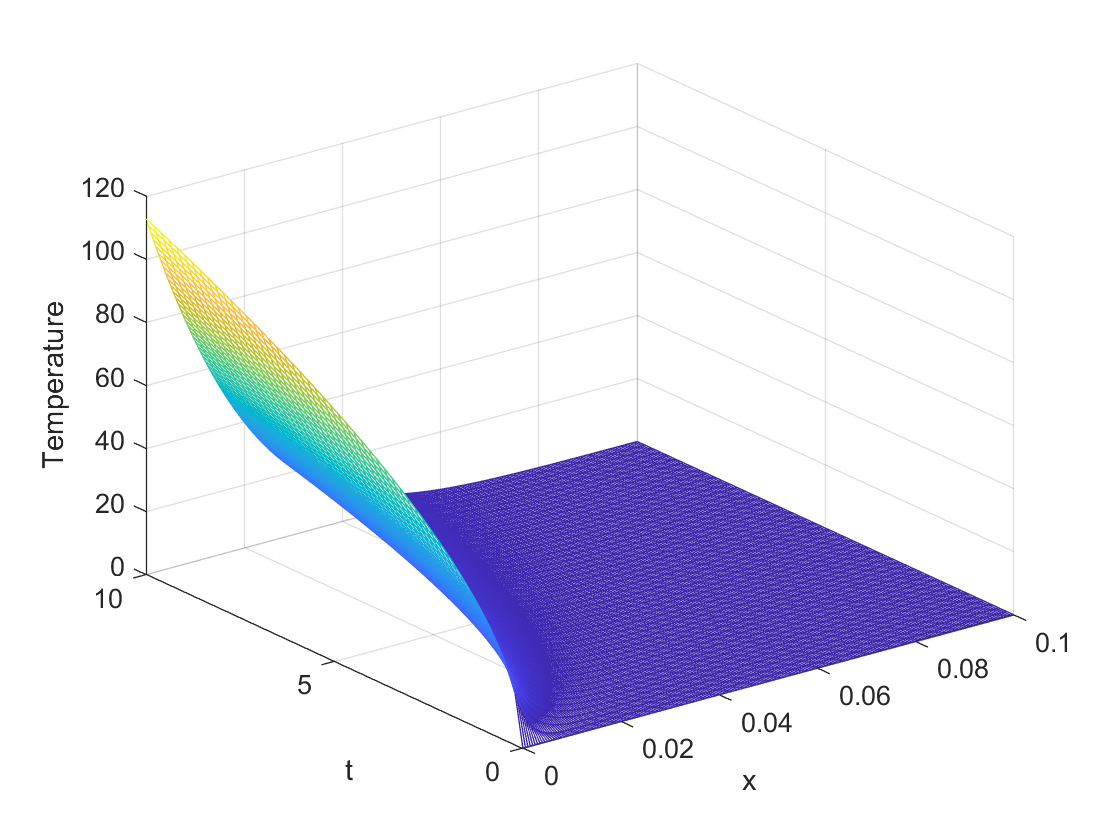

global rho cp k q
L=0.1;
k=200;
rho=10000;
cp=500;
q=1e6;
tend=10;
m=0;
x=linspace(0,L,200);
t=linspace(0,tend,50);

sol=pdepe(m,@pdex1pde,@pdex1ic,@pdex1bc,x,t);
Temperature=sol(:,:,1);
mesh(x,t,Temperature), xlabel('x'), ylabel('t'), zlabel('Temperature')

2

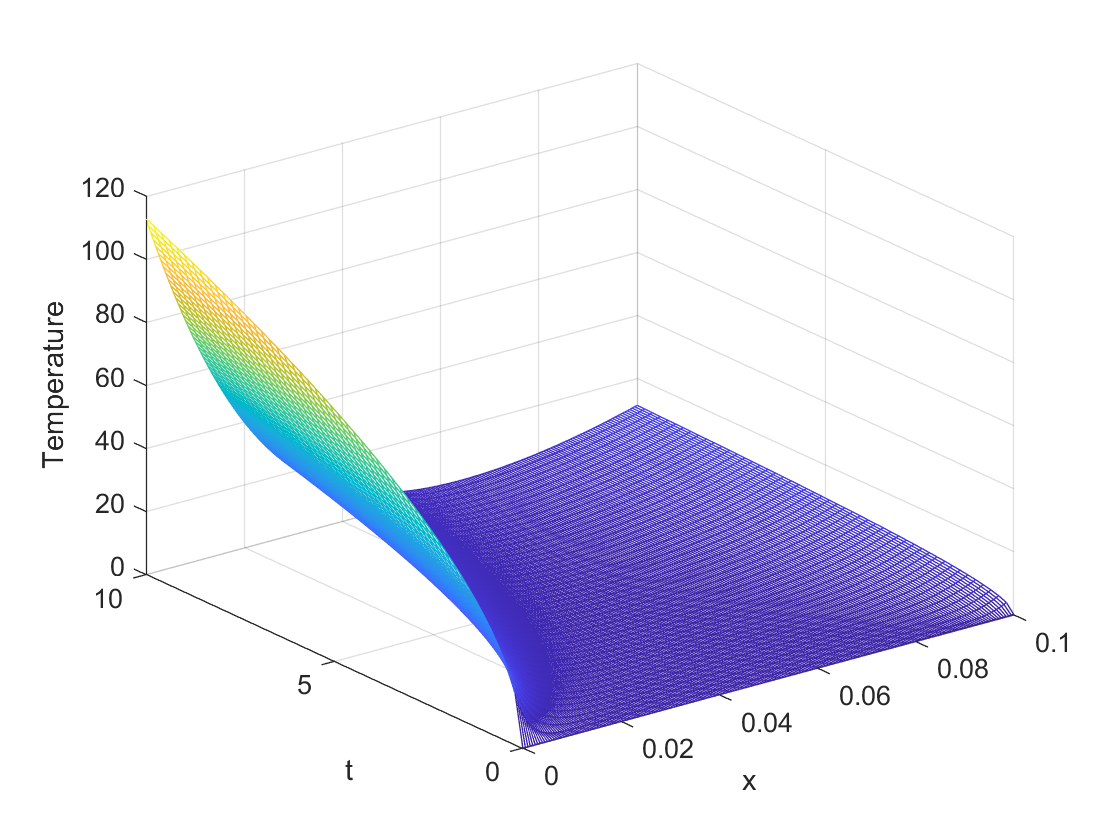

tend=10;
m=0;
x=linspace(0,L,200);
t=linspace(0,tend,50);

sol=pdepe(m,@pdex2pde,@pdex2ic,@pdex2bc,x,t);
Temperature=sol(:,:,1);
mesh(x,t,Temperature), xlabel('x'), ylabel('t'), zlabel('Temperature')

3

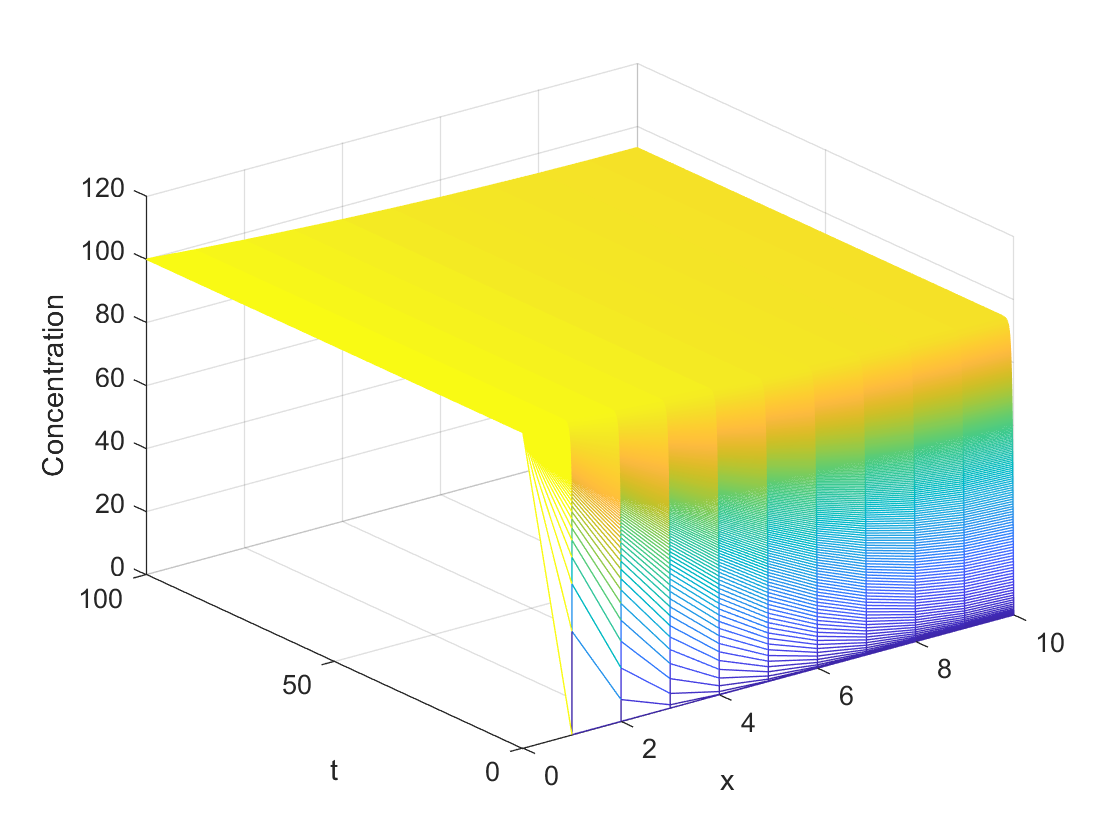

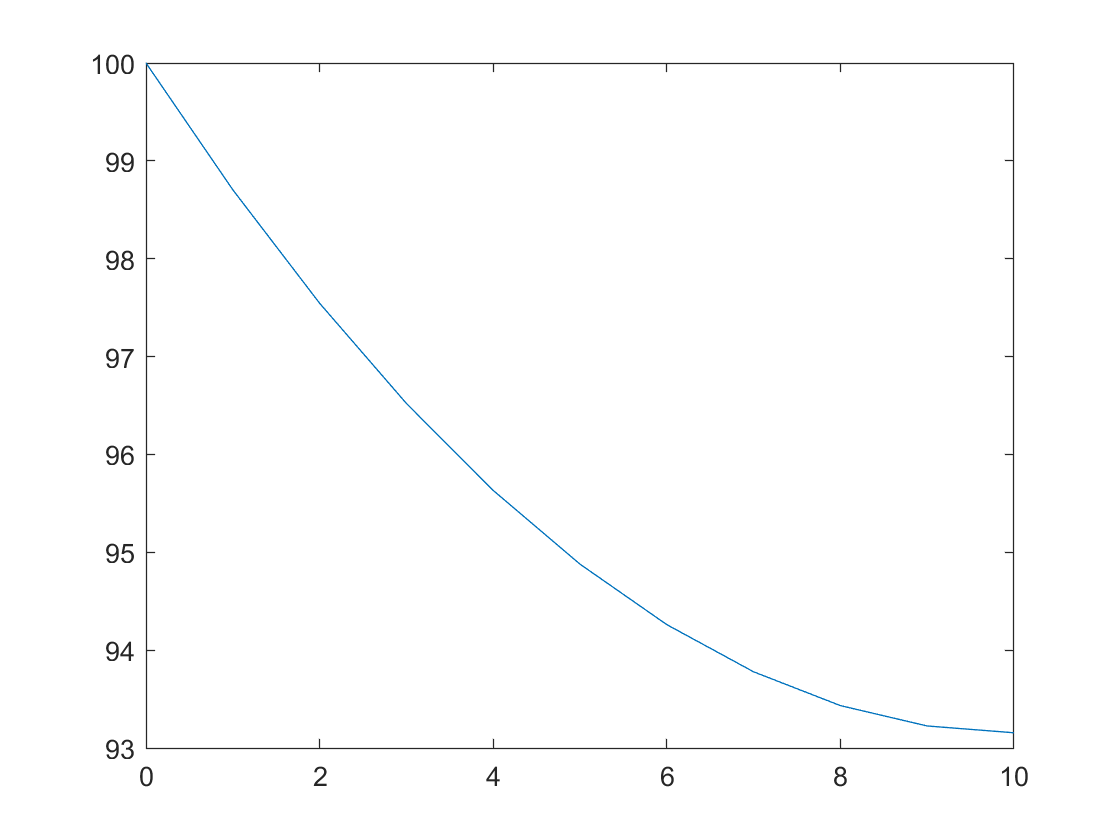

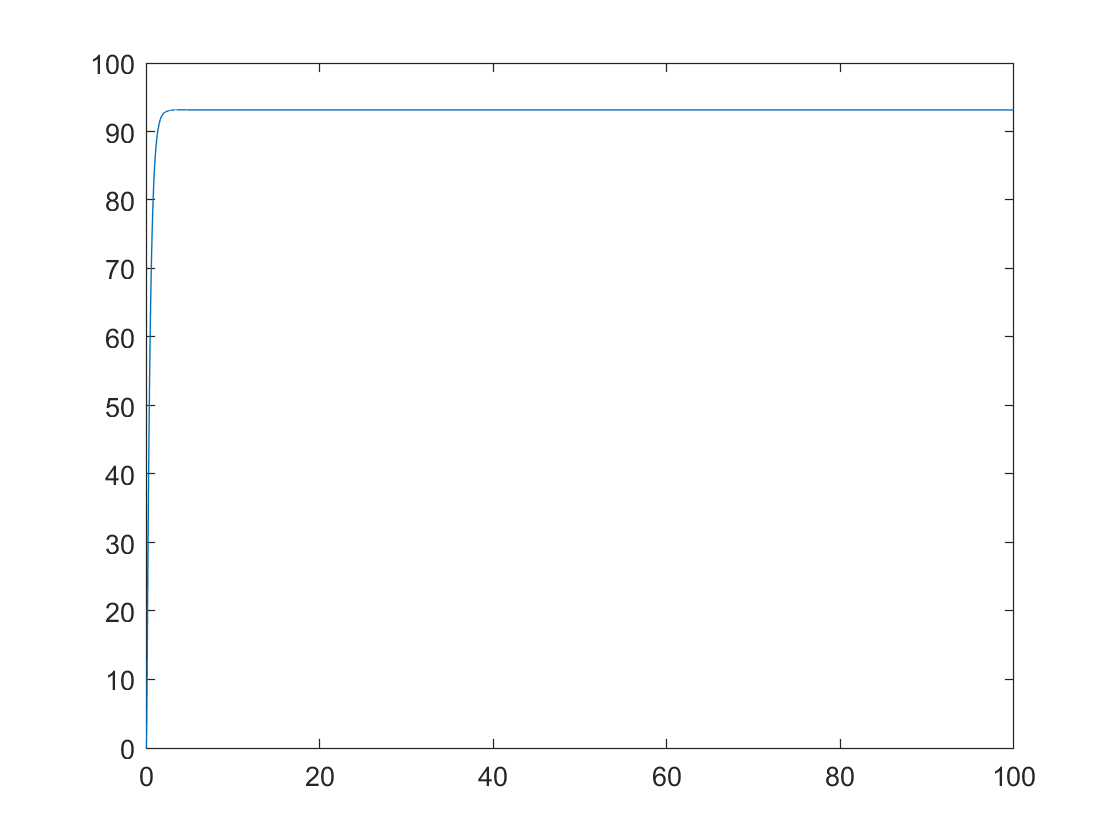

clear; close; clc;
m=0;
x=0:10;
t=0:0.005:100;

sol=pdepe(m,@pdex3pde,@pdex3ic,@pdex3bc,x,t);
Concentration=sol(:,:,1);
mesh(x,t,Concentration),xlabel('x'),ylabel('t'),zlabel('Concentration');

function [c,f,s]=pdex1pde(x,t,u,DuDx)
    global rho cp k
    c=rho*cp;
    f=k*DuDx;
    s=0;
end

function u0=pdex1ic(x)
    u0=0;
end

function [pl,ql,pr,qr]=pdex1bc(xl,ul,xr,ur,t)
    global q
    pl=q;
    ql=1;
    pr=ur;
    qr=0;
end

function [c,f,s]=pdex2pde(x,t,u,DuDx)
    global rho cp k
    c=rho*cp;
    f=k*DuDx;
    s=0;
end

function u0=pdex2ic(x)
    u0=0;
end

function [pl,ql,pr,qr]=pdex2bc(xl,ul,xr,ur,t)
    global q
    Tbulk=20;
    h=1e4;
    pl=q;
    ql=1;
    pr=h*(ur-Tbulk);
    qr=1;
end

function [c,f,s]=pdex3pde(x,t,u,DuDx)
    D=100; U=1; k=0.15;
    c=1;
    f=D*DuDx;
    s=-U*DuDx-k*u;
end

function u0=pdex3ic(x)
    u0=0;
end

function [pl,ql,pr,qr]=pdex3bc(xl,ul,xr,ur,t)
    pl=ul-100;
    ql=0;
    pr=0;
    qr=1;
end